%EXAMPLE IMPORT AND PLOT
record_name = '3000063';
number = '0007';

folder = record_name(1:2);

data = importdata("physionet.org/textdata/"+record_name+"_"+number+".txt")

data = 	1.0e+03 *

         0    0.0445    0.0006
    0.0000    0.0479    0.0006
    0.0000    0.0507    0.0006
    0.0000    0.0536    0.0006
    0.0000    0.0559    0.0007
    0.0000    0.0576    0.0007
    0.0000    0.0593    0.0007
    0.0001    0.0604    0.0007
    0.0001    0.0610    0.0007
    0.0001    0.0616    0.0007


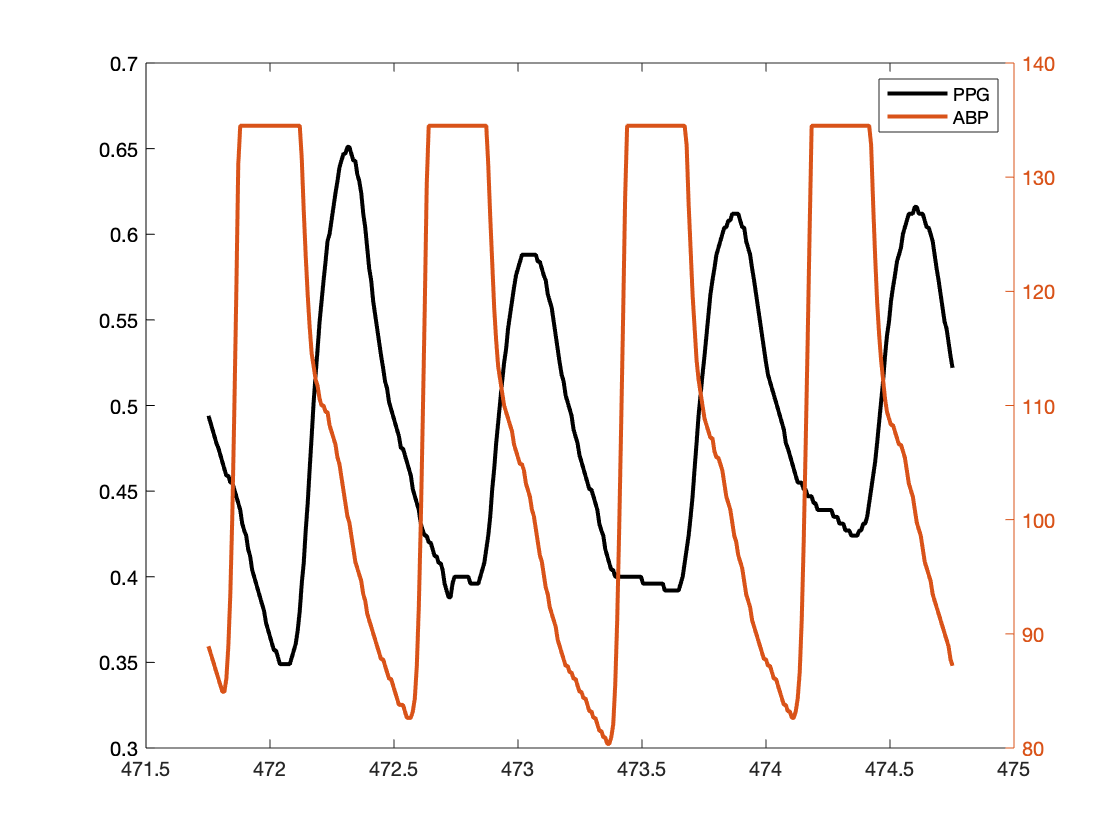


signal = data(:,2:3);
tm = data(:,1);

start_disp = round(length(tm)/4);
end_disp = start_disp+3*Fs;
clf
 plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
hold on
yyaxis right
plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
legend("PPG", "ABP")

%FILTERING

%file size thresholding already performed in Python scraper and conversion tool

%Following MIMIC cleaning process in Slapnicar et al. Blood Pressure Estimation from Photoplethysmogram 
%       Using a Spectro-Temporal Deep Neural Network


%Get list of files 
% normalise to zero mean unit variance -> 4th order Butterworth BPF with 0.5 Hz and
% 8Hz cutoffs
orig_file_dir = "physionet.org/textdata/";
fileList = dir(orig_file_dir+"*.txt") %only consider all text files

fileList = 70×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


cleaned_file_dir = "physionet.org/cleaned_data/";
if ~isdir(cleaned_file_dir)
    mkdir(cleaned_file_dir)
end


%BPF transfer function
Fs = 250;
[bpf_num, bpf_den] = butter(2, 2*pi.*[0.25 20]/(2*pi*Fs),'bandpass')

bpf_num =     0.0131         0   -0.0261         0    0.0131


bpf_den =     1.0000   -3.6504    5.0050   -3.0586    0.7040


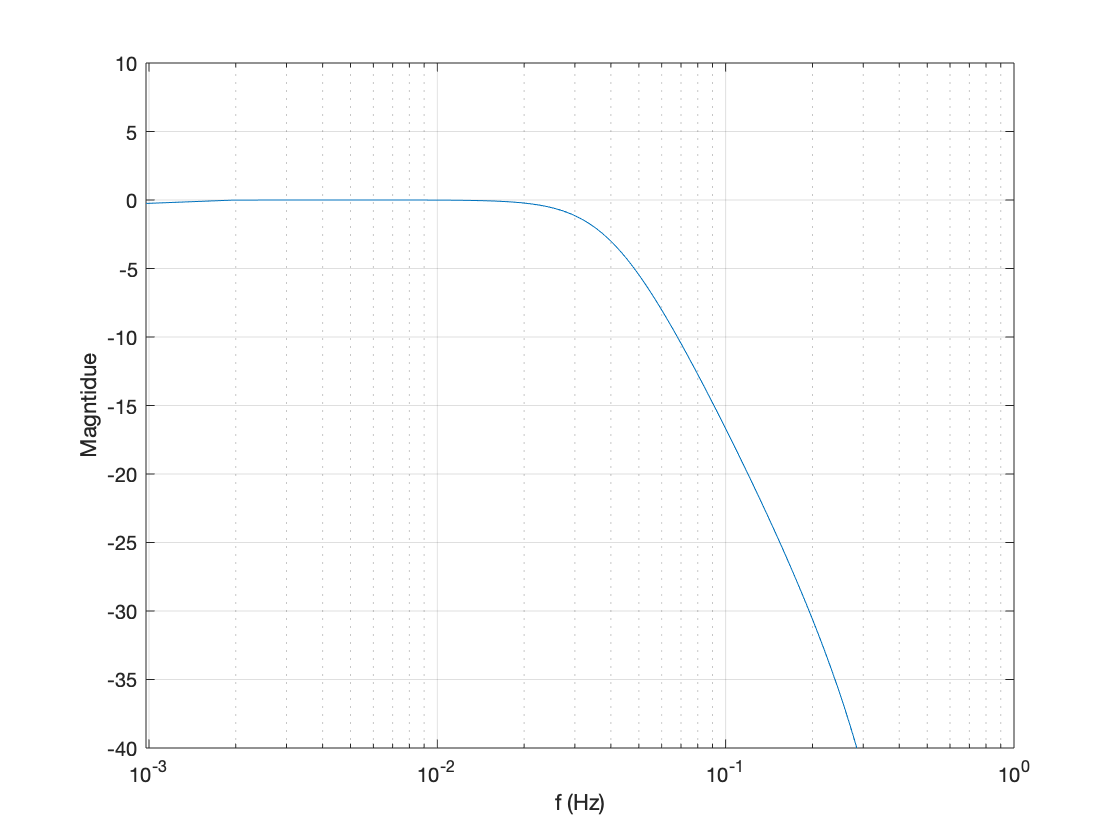

[h,w] =freqz(bpf_num, bpf_den);
clf
semilogx(w./(2*pi),20.*log10(abs(h)));
ylim([-40,10]);
grid on
xlabel('f (Hz)')
ylabel('Magntidue')




for idx = 1:length(fileList)
%      data = importdata( orig_file_dir + fileList(idx).name);
     data = cell2mat(textscan( fopen(orig_file_dir + fileList(idx).name), '%f %f %f'))
    
     discard_file = false;
     for i=2:3
         if discard_file
             continue;
         end
         
        %to check for signal flats will use diff
        %find diff that is less than some tolerance. If multiple consecutive
        %points less than that tolerance then there is a flat
        tol = 1e-4;
        diff_check = (( diff(data(:,i))<tol ) & ( diff(data(:,i))>-tol )).*1;
        multiple_pts = 30;
        if( any( movmean(diff_check, multiple_pts-1)>=1) ) %use moving mean to find multiple non changing pts
            discard_file = true;
            continue;
        end
        disp("No flats detected")
        
        data(:,i) = normalize(data(:,i));
    
        data(:,i) = filter(bpf_num, bpf_den, normalize(data(:,i)));
     end
     
     if ~discard_file
         writematrix(data, cleaned_file_dir+fileList(idx).name, 'Delimiter', 'tab')
     end
   

end

Error using cat
Dimensions of arrays being concatenated are not consistent.

Error in cell2mat (line 75)
            m{n} = cat(2,c{n,:});

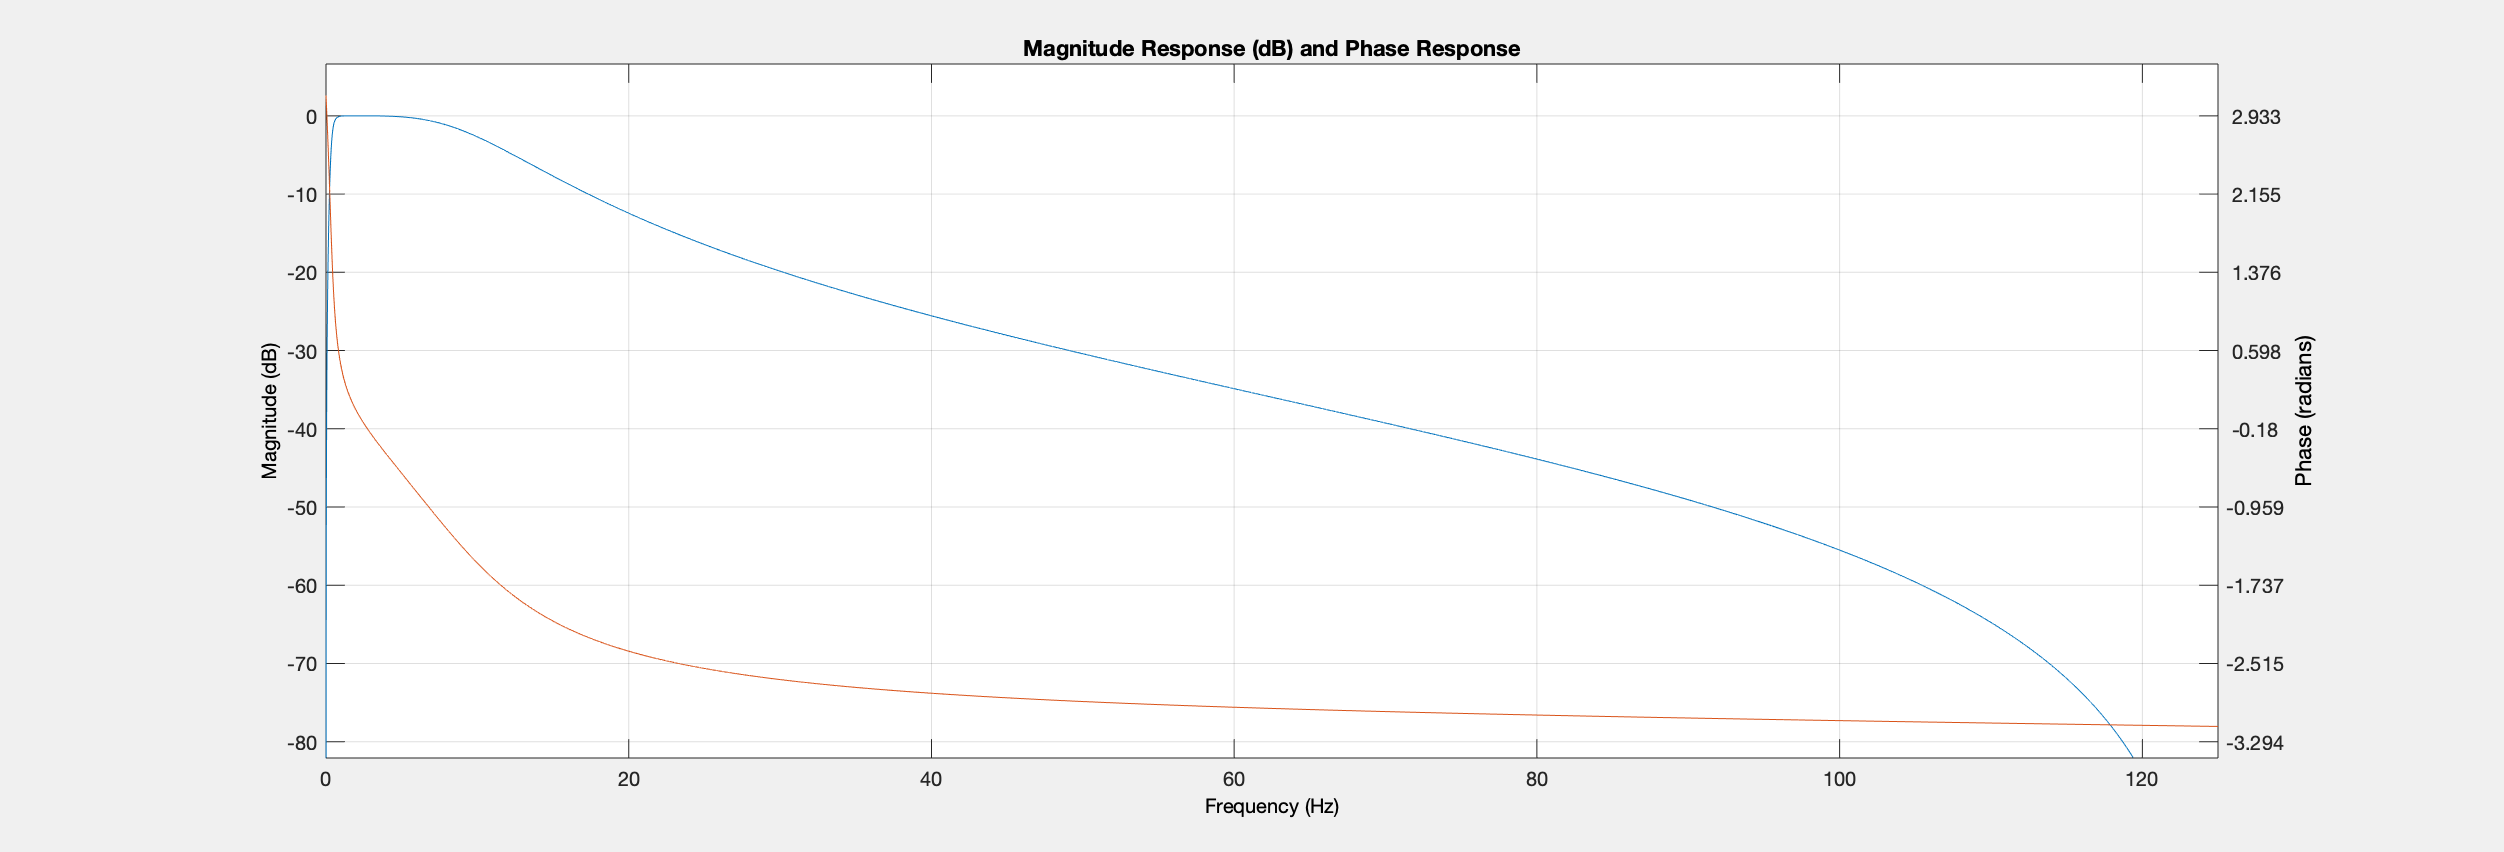

lpFilt = designfilt('bandpassiir', ...
                    'StopbandFrequency1',0.04,'PassbandFrequency1', 0.5, ...
                    'PassbandFrequency2',8,'StopbandFrequency2', 90, ...
                    'StopbandAttenuation1',40,'PassbandRipple', 2, ...
                    'StopbandAttenuation2',40, ...
                    'DesignMethod','butter','SampleRate',250);
% [h,f]freqz(lpFilt,2^16,250)

[num, den] = tf(lpFilt)

num =     0.0133         0   -0.0266         0    0.0133


den =     1.0000   -3.6438    4.9900   -3.0478    0.7016
